# TTD lines evaluations

**Description**: This code reads parameters file "parameters_cao2022broadband.txt" to evaluate the length of the true-time delay (TTD) lines. The geometry followed in this code is the Type-1 TTD, as illustrated in Fig. 7(a) below [1].

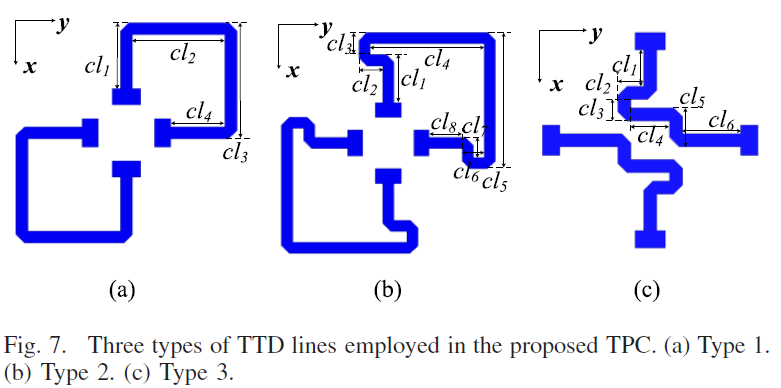

Figure 7 referenced from [1]

The Type-1 TTD line comprises four segments cl1, cl2, cl3, and cl4, that sums the total length L. The equations for each segment is evaluted as follows from geometrical restrictions with the slots on the lower and upper grounds. These geometrical restrictions are related to place the endpoints of the segments within the horizontal and vertical slots, as illustrated in Fig. 2 below. 

Following these restrictions, the length of each segment is equated as follows

    cl3 = cl1 + d

    cl4 = cl2 - d +  db_w

    L   = cl1 + cl2 + cl3 + cl4 = 2*(cl1 + cl2)

where each segment is controled by the variable cl1, and the total length of the line sums L. We follow the paper convention with the hook pinned to slot centres (-d, 0) and (0, -d):

Given L_target and cl1_target as free parameters:

    cl2 = L/2 - cl1

    cl3 = cl1 + d

    cl4 = L/2 - cl1 - d


clear; clc;
 
% ---- USER INPUTS ------------------------------------------------------
params_file    = 'parameters_cao2022broadband_TTD_type_1.txt';                % file written by CST

polyline_file  = 'L5_TTD_A_Type_1_polygon_CST_xyz_triplets.txt';
L_TTD       = 4.4;     % mm; Fig.8 reference values: 3.2 / 4.4 / 6.8 / 9.2 / 10.4
cl1_target     = 0.4;     % mm; clearance from upper slot

% -----------------------------------------------------------------------
 
pat = '^\s*([A-Za-z_][A-Za-z_0-9]*)\s*=\s*"([^"]*)"\s*(?:"([^"]*)")?\s*$';
 
% ---- Read parameters file, detect CRLF --------------------------------
fid = fopen(params_file, 'rb');
if fid < 0, error('Cannot open %s', params_file); end
raw_bytes = fread(fid, Inf, 'uint8=>char')';
fclose(fid);
 
if ~isempty(strfind(raw_bytes, sprintf('\r\n')))
    eol = sprintf('\r\n');
else
    eol = sprintf('\n');
end
 
raw_lines = regexp(raw_bytes, '\r?\n', 'split');
if ~isempty(raw_lines) && isempty(raw_lines{end}), raw_lines(end) = []; end
 
% ---- Parse parameters file: key -> value lookup -----------------------
pat_with    = '^\s*([A-Za-z_][A-Za-z_0-9]*)\s*=\s*"([^"]*)"\s+"([^"]*)"\s*$';
pat_without = '^\s*([A-Za-z_][A-Za-z_0-9]*)\s*=\s*"([^"]*)"\s*$';

keys = {}; vals = {}; cmts = {};
for i = 1:numel(raw_lines)
    L = raw_lines{i};
    tok = regexp(L, pat_with, 'tokens', 'once');
    if ~isempty(tok)
        cmt = tok{3};
    else
        tok = regexp(L, pat_without, 'tokens', 'once');
        if isempty(tok), continue; end
        cmt = '';
    end
    if ~any(strcmp(keys, tok{1}))
        keys{end+1,1} = tok{1};
        vals{end+1,1} = tok{2};
        cmts{end+1,1} = cmt;
    end
end
 

% ---- Helper: numeric lookup -------------------------------------------
get_num = @(name) str2double(vals{find(strcmp(keys, name), 1, 'first')});
 
d      = get_num('d');
slot_l = get_num('slot_l');
mic_w  = get_num('mic_w');
a      = get_num('a');
db_l      = get_num('m_l');
db_w      = get_num('m_w');
slot_w      = get_num('slot_w');
 
if any(isnan([d, slot_l, mic_w, a]))
    error('Could not read numeric d / slot_l / mic_w / a from %s', params_file);
end
 
% ---- Type-1 calculations -------------------------------------------------

 
% ---- Write the parameters file with reference comments ----------------
s_center=4*mic_w;
updates = struct('s_center', sprintf('%.6g', s_center));
upd_keys = fieldnames(updates);
 
fid = fopen(params_file, 'wb');
if fid < 0, error('Cannot write %s', params_file); end
for i = 1:numel(raw_lines)
    L = raw_lines{i};
    tok = regexp(L, pat_with, 'tokens', 'once');
    if isempty(tok)
        fwrite(fid, [L eol]);
        continue;
    end
    key = tok{1}; val = tok{2};
    if numel(tok) >= 3, cmt = tok{3}; else, cmt = ''; end
 
    % overwrite numeric s_center with computed values
    if any(strcmp(upd_keys, key)) && ~isnan(str2double(val))
        val = updates.(key);
    end
    
    if isempty(cmt)
        new_line = sprintf('%s="%s"', key, val);
    else
        new_line = sprintf('%s="%s" "%s"', key, val, cmt);
    end

    fwrite(fid, [new_line eol]);
end
fclose(fid);
fprintf('Wrote %s\n', params_file);

Wrote parameters_cao2022broadband_TTD_type_1.txt


 
% ---- Regenerate the polyline file (symbolic, slot-centre pinned) ------
poly_lines = { ...
    'd+slot_w/2 0 (z_L5+z_L6)/2', ...
    's_center/2 0 (z_L5+z_L6)/2', ...
    's_center/2 s_center/2 (z_L5+z_L6)/2', ...
    '0 s_center/2 (z_L5+z_L6)/2', ...
    '0 d+slot_w/2 (z_L5+z_L6)/2'};
 
fid = fopen(polyline_file, 'wb');
if fid < 0, error('Cannot write %s', polyline_file); end
for k = 1:numel(poly_lines), fwrite(fid, [poly_lines{k} eol]); end
fclose(fid);
fprintf('Wrote %s\n', polyline_file);

Wrote L5_TTD_A_Type_1_polygon_CST_xyz_triplets.txt


#### References

[1] A Broadband Low-Profile Transmitarray Antenna by Using Differentially Driven Transmission Polarizer With True-Time Delay